## A tutorial of:

`1) downloading needed files from brain observatory api and converting them to matlab tables`

`2) building a brain_observatory_cache object to a) get general information of the whole brain observatory dataset`

`                                                b) select sessions by`

`                                                conditions such as brain`

`                                                areas, imaging depth and`

`                                                stimuli`

`                                                c) download nwb files of selected sessions`

`3) importing imgaging data from nwb files to a) plot fluorescence traces`

`                                             b) transform them into raster formats for decoding`

## important information about this dataset:

an experiment container (named by allen institute) contains a set of subexperiments (defined by us as one subexperiment only adopted one kind of stimuli) operated on a singe mouse, recorded in a single brain space (same targeted_structure and same imaging depth), performed during one out of three sessions (allen institue equated session with experiment), that may have adopted the same stimulus as another subexperiment in another session within the same experiment container.

our shorthand: container = experiment_container

the three names we use: container > session > subexperiment

## 0)

% set your base_directory 
base_dir_name = '/om/user/xf15/Brain-Observatory-Toolbox/';

% add path to sdk
addpath([base_dir_name, 'sdk/'])

## 1) download needed files from brain observatory api and converting them to matlab tables

get_files_from_brain_obs_api()

load('references')

## 2) build a brain_observatory_cache object

% building a brain_observatory_cache object
boc = brain_observatory_cache (references)

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: []
                   stimuli: []
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []


## 2a) get general information of the whole brain observatory dataset

boc.get_total_of_containers()

ans = 199

boc.get_all_imaing_depths()

ans = 12×1 cell array
    '175'
    '250'
    '265'
    '275'
    '300'
    '320'
    '325'
    '335'
    '350'
    '365'
    '375'
    '435'


boc.get_all_cre_lines()

ans = 6×1 cell array
    'Cux2-CreERT2'
    'Emx1-IRES-Cre'
    'Nr5a1-Cre'
    'Rbp4-Cre_KL100'
    'Rorb-IRES2-Cre'
    'Scnn1a-Tg3-Cre'


boc.get_all_targeted_structures()

ans = 6×1 cell array
    'VISal'
    'VISam'
    'VISl'
    'VISp'
    'VISpm'
    'VISrl'


boc.get_all_session_types()

ans = 4×1 cell array
    'three_session_A'
    'three_session_B'
    'three_session_C'
    'three_session_C2'


boc.get_all_stimuli()

ans = 9×1 cell array
    'drifting_gratings'
    'locally_sparse_noise_eight_degree'
    'locally_sparse_noise_four_degree'
    'natural_movie_one'
    'natural_movie_three'
    'natural_movie_two'
    'natural_scene'
    'spontaneous_activity'
    'static_gratings'


boc.get_summary_of_container_along_targeted_structures()

     VISal      35 
     VISam      25 
     VISl       38 
     VISp       66 
     VISpm      36 
     VISrl      16 


boc.get_summary_of_containers_along_imaing_depths()

     175      53 
     250       1 
     265       1 
     275      75 
     300       4 
     320       1 
     325       3 
     335       3 
     350      33 
     365       1 
     375      40 
     435       1 


boc.get_summary_of_containers_along_depths_and_structures()

ans = 13×7 table
             VISal    VISam    VISl    VISp    VISpm    VISrl    total
             _____    _____    ____    ____    _____    _____    _____

    175       8        5       10      11      11        5        50  
    250       0        0        0       0       0        0         0  
    265       1        0        0       0       0        0         1  
    275      12        9       15      20      11        5        72  
    300       1        0        1       1       1        0         4  
    320       0        1        0       0       0        0         1  
    325       0        1        1       0       1        

## 2b) select sessions by conditions such as brain areas, imaging depth and stimuli

% Example: search for experiments that primary visual cortex was
% recorded at 275 mm deep as drifting gratings were shown

% reinitialize to have a "clean start"
boc = brain_observatory_cache (references)

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: []
                   stimuli: []
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []



% set conditions
boc.stimuli = 'drifting_gratings'

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: []
                   stimuli: 'drifting_gratings'
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []


boc.targeted_structure = 'VISp'

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: []
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: []
              container_id: []
                session_id: []


boc.imaging_depth = 275

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: []
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: []
                session_id: []



% %  all filters are optional; all sessions will be returned if no filter
% %  is applied 
% % 
% % you can also use brain_observatory_cache to look up manifest of
% % selected session(s) by container_id or session_id
% %
% boc = brain_observatory_cache(references)
% boc.container_id = 527550471
% boc.session_id = 527745328

%  pass conditions
boc.get_session()
boc

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: [20×14 table]
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: []
                session_id: []



% get manifest of selected sessions
boc.selected_session_table

ans = 20×14 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth                    name                     specimen_id      stimulus_name                                    storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen  
    ______________________    _______________________    _________________    __________    _____________    _____________________________________    ___________    _________________    __________________________________________


% get id of the first session in the current list for fun
session_id = boc.selected_session_table.id(1)

session_id = 527745328

## 2c) download nwb files of selected sessions

% download nwb file of the first session in selected sessions into a directory called nwb_files
boc.session_id = session_id

boc =   brain_observatory_cache with properties:

             session_table: [648×14 table]
           container_table: [216×13 table]
    selected_session_table: [20×14 table]
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: []
                session_id: 527745328


boc.get_session()
nwb_dir_name = [base_dir_name,'nwb_files/'];

% the size of a nwb file is at the scale of 100 MB
boc.get_session_data(nwb_dir_name);

desired nwb file already exists

## 3 import imgaging data from nwb files

% add path to nwb files
addpath ([base_dir_name, 'nwb_files/'])

## 3a) plot fluorescence traces of the selcted cell from the selected session

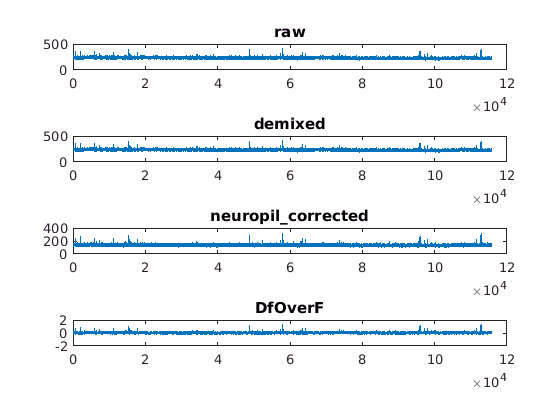

% get fluoroscence traces of all cells in this session and plot ones of
% selected cells
session_id = 527745328;
cell_specimen_id = 529022196;

[raw,demixed,neuropil_corrected,DfOverF] = get_fluorescence_traces (session_id,cell_specimen_id);

## 3b) transform data of the selected fluorescence trace of the selected subexperiment into raster format

raster_dir_name = [base_dir_name, 'raster/'];

stimuli = 'drifting_gratings';
fluorescence_trace = DfOverF;

current_raster_dir_name = transform_fluorescenece_trace_into_raster_format(fluorescence_trace,...
    session_id, stimuli,raster_dir_name);

/om/user/xf15/Brain-Observatory-Toolbox/raster/drifting_gratings_527745328/ already exists